% clear variables in workspace and close all figures
clearvars; close all;

% reading the data
% data = readtimetable('../Datasets/Saint John/SaintJohnEnergy.xlsx');
data = readtimetable('../Datasets/Ontario/OntarioIESO.xlsx');

TR = timerange('2016-01-01','2019-12-31');
data = data(TR, :);   % new total dataset

% Normalizing the variables

% y = (x - min) / (max - min)
tmp = timetable2table(data);
maxdp = max(table2array(tmp(:, 2:end)));    % takes the max and min of each variable in the dataset
mindp = min(table2array(tmp(:, 2:end)));
tmp.DateTime = [];
normalize = (table2array(tmp) - mindp) ./ (maxdp - mindp);

% creating the normalized dataset
ndata = data;
ndata.DemandMW = normalize(:, 1);
ndata.Temperature = normalize(:, 2);
ndata.Humidity = normalize(:, 3);
ndata.Dewpoint = normalize(:, 4);
ndata.WindDirection = normalize(:, 5);
ndata.WindSpeed = normalize(:, 6);

clearvars -except data ndata mindp maxdp


TR = timerange('2016-01-01','2018-12-31');
trainvald = ndata(TR, :);   % training data

TR = timerange('2019-01-01','2019-12-31');
testd = ndata(TR, :);   % testing data

% TR = timerange('2016-01-01','2019-12-31');
% ndata = ndata(TR, :);   % new total dataset

## Training the Forecasters

### Inputs and Targets Creation


[inputs, blf_outputs, clf_outputs, time_outputs, p] = InputsCreation(trainvald);

% clearvars -except data ndata mindp maxdp clf_outputs blf_outputs inputs time_outputs p trainvald testd

### Base Load Forecaster training

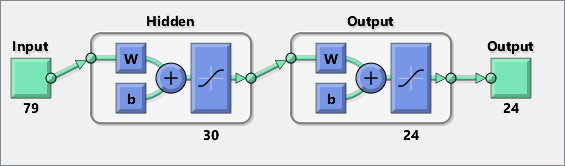

clear net

x = inputs;
t = blf_outputs;

% trainFcn = 'trainlm';  % Levenberg-Marquardt backpropagation. Was quite slow in training
trainFcn = 'trainrp';   % Resilient backpropagation


% Create a Fitting Network
hiddenLayerSize = 30;
% net = feedforwardnet(hiddenLayerSize,trainFcn);
net = fitnet(hiddenLayerSize,trainFcn);

% logsig = 1 / 1 + e^(-z) ; tansig = 2/(1+exp(-2*n))-1;
% using tansig gave better predictions.
% Increasing the no. of neurons didn't make logsig prediction better.
net.layers{1}.transferFcn = 'tansig'; % converts the output layer's function to sigmoid
net.layers{2}.transferFcn = 'tansig'; % converts the output layer's function to sigmoid


% Setup Division of Data for Training, Validation, Testing
net.divideParam.trainRatio = 80/100;
net.divideParam.valRatio = 20/100;
net.divideParam.testRatio = 0/100;
% net.divideFcn = 'divideblock';


% Train the Network
[net,trBLF] = train(net,x,t);

% % Getting the datasets used in training, validation, and testing
% train_set = blf_outputs(:,trBLF.trainInd);
% val_set = blf_outputs(:,trBLF.valInd);
% test_set = blf_outputs(:,trBLF.testInd);

% Test the Network
% y = net(x);
% e = gsubtract(t,y);
% performance = perform(net,t,y)

% View the Network
newView(net)

blf_net = net;

### Change in the Load Forecaster Training

clear net

x = inputs;
t = clf_outputs;

% trainFcn = 'trainlm';  % Levenberg-Marquardt backpropagation. Was quite slow in training
trainFcn = 'trainrp';   % Resilient backpropagation


% Create a Fitting Network
hiddenLayerSize = 30;
% net = feedforwardnet(hiddenLayerSize,trainFcn);
net = fitnet(hiddenLayerSize,trainFcn);

% logsig = 1 / 1 + e^(-z) ; tansig = 2/(1+exp(-2*n))-1;
% using tansig gave better predictions.
% Increasing the no. of neurons didn't make logsig prediction better.
net.layers{1}.transferFcn = 'tansig'; % converts the output layer's function to sigmoid
net.layers{2}.transferFcn = 'tansig'; % converts the output layer's function to sigmoid


% Setup Division of Data for Training, Validation, Testing
net.divideParam.trainRatio = 80/100;
net.divideParam.valRatio = 20/100;
net.divideParam.testRatio = 0/100;
% net.divideFcn = 'divideblock';

% Train the Network
[net,trCLF] = train(net,x,t);

% % Getting the datasets used in training, validation, and testing
% train_set = clf_outputs(:,trCLF.trainInd);
% val_set = clf_outputs(:,trCLF.valInd);
% test_set = clf_outputs(:,trCLF.testInd);

% Test the Network
% y = net(x);
% e = gsubtract(t,y);
% performance = perform(net,t,y)

% View the Network
newView(net)

clf_net = net;

## Predict the whole dataset (train +validation + test sets)

% Generating the inputs for the entire dataset
[inputs, blf_outputs, clf_outputs, time_outputs, p] = InputsCreation(ndata);

### Generate BLF forecasts

% generate the forecasts
raw_blf = blf_net(inputs);

% denormalize predicted values
yBLF = raw_blf * (maxdp(1) - mindp(1)) + mindp(1);

% these are the actual, denormalized load demand values 
actuals = blf_outputs * (maxdp(1) - mindp(1)) + mindp(1);

### Generate CLF forecasts

% generate the forecasts
raw_clf = clf_net(inputs) + p(:,1:end-1);

% denormalize predicted values
yCLF = raw_clf * (maxdp(1) - mindp(1)) + mindp(1);

### Generate RLS forecasts

days = size(yBLF);
days = days(2);

% calls the rls combiner function
yRLS = RLS_Combiner(raw_blf, raw_clf, blf_outputs, days); % uses normalized values as inputs

% denormalize the rls combination
yRLS = yRLS*(maxdp(1) - mindp(1)) + mindp(1);

len = size(trBLF.trainMask{1});
len = len(2);   % length of the data used fo training and validation

% separate train, test and validation sets
trn_BLF = yBLF(:, 1:len) .* trBLF.trainMask{1};
% tst_BLF = yBLF .* trBLF.testMask{1};
val_BLF = yBLF(:, 1:len) .* trBLF.valMask{1};
tst_BLF = yBLF(:, len+1:end);


trn_CLF = yCLF(:, 1:len) .* trCLF.trainMask{1};
% tst_CLF = yCLF .* trCLF.testMask{1};
val_CLF = yCLF(:, 1:len) .* trCLF.valMask{1};
tst_CLF = yCLF(:, len+1:end);

% the rls prediction wasn't separated into these sets

### Calculate errors


%BLF errors
eBLF = actuals - yBLF;
blf_APEs = abs(eBLF) ./ abs(yBLF);
blf_MAPE = 100*mean(mean(blf_APEs)); % blf MAPE

trn_BLF_MAPE = 100 * mean(mean(blf_APEs(:,trBLF.trainInd)));
% tst_BLF_MAPE = 100 * mean(mean(blf_APEs(:,trBLF.testInd)));
val_BLF_MAPE = 100 * mean(mean(blf_APEs(:,trBLF.valInd)));
tst_BLF_MAPE = 100 * mean(mean(blf_APEs(:,len+1:end)));


% CLF errors
eCLF = actuals - yCLF;
clf_APEs = abs(eCLF) ./ abs(yCLF);
clf_MAPE = 100*mean(mean(clf_APEs));    % clf MAPE

trn_CLF_MAPE = 100 * mean(mean(clf_APEs(:,trCLF.trainInd)));
% tst_CLF_MAPE = 100 * mean(mean(clf_APEs(:,trCLF.testInd)));
val_CLF_MAPE = 100 * mean(mean(clf_APEs(:,trCLF.valInd)));
tst_CLF_MAPE = 100 * mean(mean(clf_APEs(:,len+1:end)));


% RLS errors
eRLS = actuals - yRLS;
rls_APEs = abs(eRLS) ./ abs(yRLS);
rls_MAPE = 100*mean(mean(rls_APEs));    % rls MAPE




## Plot actual values and forecasts for BLF

time_trainval = time_outputs(1:len*24);
time_test = time_outputs(len*24+1:end);

figure;

sp(1) = subplot(311);

% plot actual values
plot(time_outputs, actuals(:), 'DisplayName','Actual Values')
title('BLF forecasts')
ylabel('Load demand (MW)')
grid on; 
hold on;

% plot training set
DisplayName = num2str(trn_BLF_MAPE,'TrainSet (MAPE = %.2f%%)');
plot(time_trainval,trn_BLF(:), 'DisplayName', DisplayName)

% plot test set
DisplayName = num2str(tst_BLF_MAPE, 'TestSet (MAPE = %.2f%%)');
plot(time_test,tst_BLF(:), 'DisplayName', DisplayName)

% plot validation set
DisplayName = num2str(val_BLF_MAPE, 'ValidationSet (MAPE = %.2f%%)');
plot(time_trainval,val_BLF(:), 'DisplayName', DisplayName)

legend('show')

## Plot actual values and CLF forecasts 

sp(2) = subplot(312);

% plot actual values
plot(time_outputs, actuals(:), 'DisplayName','Actual Values')
title('CLF forecasts')
ylabel('Load demand (MW)')
grid on; 
hold on;


% plot training set
DisplayName = num2str(trn_CLF_MAPE,'TrainSet (MAPE = %.2f%%)');
plot(time_trainval,trn_CLF(:), 'DisplayName', DisplayName)

% plot test set
DisplayName = num2str(tst_CLF_MAPE, 'TestSet (MAPE = %.2f%%)');
plot(time_test,tst_CLF(:), 'DisplayName', DisplayName)

% plot validation set
DisplayName = num2str(val_CLF_MAPE, 'ValidationSet (MAPE = %.2f%%)');
plot(time_trainval,val_CLF(:), 'DisplayName', DisplayName)

legend('show')
% linkaxes(sp)

## Plot actual values and RLS forecasts 

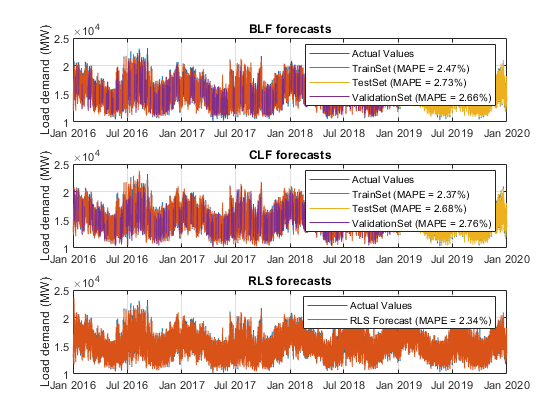

sp(3) = subplot(313);

% plot actual values
plot(time_outputs, actuals(:), 'DisplayName','Actual Values')
title('RLS forecasts')
ylabel('Load demand (MW)')
grid on; 
hold on;

% plot rls forecast
DisplayName = num2str(rls_MAPE, 'RLS Forecast (MAPE = %.2f%%)');
plot(time_outputs,yRLS(:), 'DisplayName', DisplayName)

legend('show')
linkaxes(sp)

### Plots of the entire dataset as a whole

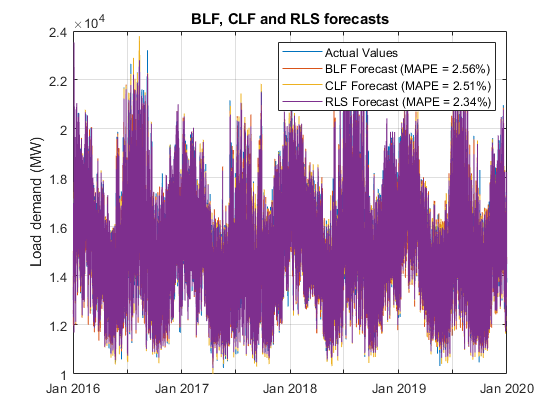

figure;

% plot actual values
plot(time_outputs, actuals(:), 'DisplayName','Actual Values')
title('BLF, CLF and RLS forecasts')
ylabel('Load demand (MW)')
grid on; 
hold on;

% plot blf forecast
DisplayName = num2str(blf_MAPE, 'BLF Forecast (MAPE = %.2f%%)');
plot(time_outputs,yBLF(:), 'DisplayName', DisplayName)

% plot clf forecast
DisplayName = num2str(clf_MAPE, 'CLF Forecast (MAPE = %.2f%%)');
plot(time_outputs,yCLF(:), 'DisplayName', DisplayName)

% plot rls forecast
DisplayName = num2str(rls_MAPE, 'RLS Forecast (MAPE = %.2f%%)');
plot(time_outputs,yRLS(:), 'DisplayName', DisplayName)
legend('show')

## Forecasting a Portion of The Dataset

clearvars -except data ndata mindp maxdp clf_outputs blf_outputs inputs blf_net clf_net

### BLF - 24H ahead predictions (Day by Day)

We forecast one day at a time using the actual values of the previous day as inputs.

clear by bx bt

index = 35; % number of days to forecast
bt = blf_outputs(:, end-index+1 : end); %The target variable for the desired days
lend = index;

% predicts day by day using the intial inputs and the generated inputs
% that uses the actual value of the previous day.
for i=1:lend
    bx(:, i) = inputs(:, end-index+1);  % gets the original input of the day we are about to predict
    if i > 1
        bx(1:24, i) = bt(1:24, i-1); % actual value from previous day
    end
    
    by(:, i) = blf_net(bx(:, i)); % The forecasts
    index = index - 1;  % reduces index so we can move forward to forecasts the next day
end

time = data.DateTime(end - lend*24 +1 : end); % gets the timeline for the prediction

% by = reshape(by, [], 1); % merges all columns to one
% bt = reshape(bt, [], 1);

### CLF - 24H ahead predictions (Day by Day)

The BLF and CLF always have the same input.

We forecast one day at a time using the actual values of the previous day as inputs. Since it's a 24h ahead prediction, the actual load of yesterday can be added to the clf forecast to get the final clf forecast. If's a larger horizon  > 24h or 1 day; the clf final forecast of yesterday can be added instead.

clear cy cx ct

index = lend;   % number of days to forecast
% ct = clf_outputs(:, end-index+1 : end); %The target variable for the desired days

prev_day_load = ndata.DemandMW(time - days(1));  % takes the actual demand of yesterday
prev_day_load = buffer(prev_day_load,24);   % the final clf forecast

% predicts day by day using the intial inputs and the generated inputs
% that uses the actual value of the previous day.
for i=1:lend
    cx(:, i) = inputs(:, end-index+1);   % gets the original input of the day we are about to predict
 
    if i > 1
        cx(1:24, i) = bt(1:24, i-1); % actual value from previous day
    end
    
    cy(:, i) = clf_net(cx(:, i)) + prev_day_load(:,i); % The final forecasts
    index = index - 1;  % reduces index so we can move forward to forecasts the next day
end

% cy = reshape(cy, [], 1); % merges all columns to one
% ct = reshape(ct, [], 1);

### RLS Combiner

% Inputs
blfy = by;
clfy = cy;

% Desired value
desired = bt;

days = size(blfy);
days = days(1, 2);  % gets the number of days we are forecasting

[rlsy, weight] = RLS_Combiner(blfy, clfy, desired, days); % calls the rls combiner

## Visualizing the results

% clearvars -except data ndata mindp maxdp clf_outputs blf_outputs inputs blf_net clf_net blfy clfy desired rlsy time

blfy = reshape(blfy, [], 1); % merges all columns to one
clfy = reshape(clfy, [], 1); 
rlsy = reshape(rlsy, [], 1); 
desired = reshape(desired, [], 1);

% Denormalization
blfy = blfy*(maxdp(1) - mindp(1)) + mindp(1);   % gets back the original data using the min and max Demand
clfy = clfy*(maxdp(1) - mindp(1)) + mindp(1);
rlsy = rlsy*(maxdp(1) - mindp(1)) + mindp(1);
desired = desired*(maxdp(1) - mindp(1)) + mindp(1);

% MAPE calculations
blf_MAPE = mean(abs(desired'-blfy')/desired')*100;  % calculate mape after denormalization could make the mape smaller due to high denominator values
clf_MAPE = mean(abs(desired'-clfy')/desired')*100;
rls_MAPE = mean(abs(desired'-rlsy')/desired')*100;

% calculating the errors
blfe = gsubtract(desired, blfy);
clfe = gsubtract(desired, clfy);
rlse = gsubtract(desired, rlsy);

% Plots
figure
subplot(2,1,1)
plot(time, desired, time, blfy, time, clfy, time, rlsy)
legend('Actual Demand', 'BLF Forecast', 'CLF Forecast', 'RLS Combiner')
grid

subplot(2,1,2)
plot(time, blfe, time, rlse)
legend('BLF Error', 'RLS Error')
% plot(time, blfe, time, clfe, time, rlse)
% legend('BLF Error', 'CLF Error', 'RLS Error')
grid